# Data Visualisation

## Data Import

% Import data from text file
Processed_Data = readtable("/MATLAB Drive/VVCE_FDP_OCT2023/Data/Processed_Data.csv");

% Display results
Processed_Data

Processed_Data = 768×9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin     BMI      Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ______    _________________    ___    _____

        6         148           72            35             156           33.6          0.627          50       1  
        1          85           66            29             156           26.6          0.351          31       0  
        8         183           64            29             156           23.3          0.672          32       1  
        1          89           66            23              94           28.1

## Data Visualisation

Goal-Build an AI(ML/DL) Model to predict diabetes condition of a person with the diagnostic data

Inputs vs. Outputs

Input(Glucose) vs. Output(Class)

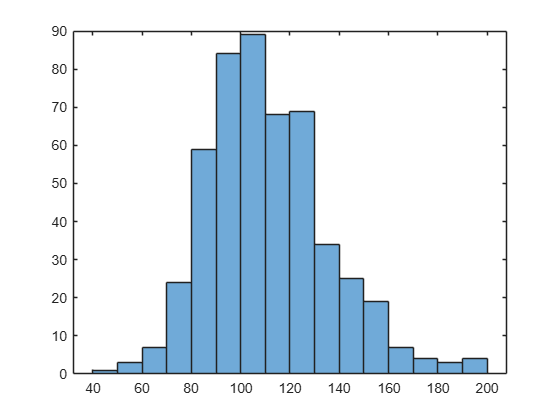

%Non-Diabetic Group
histogram(Processed_Data.Glucose(Processed_Data.Class==0))

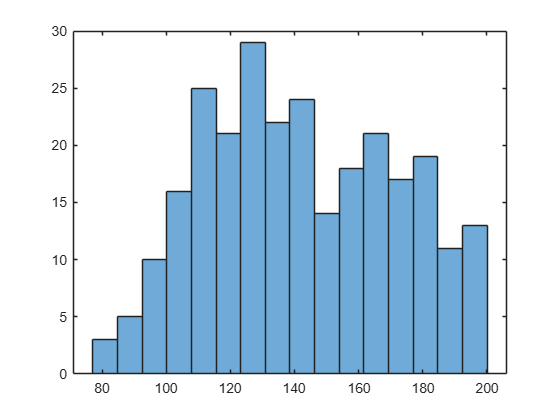

%Diabetic Group
histogram(Processed_Data.Glucose(Processed_Data.Class==1),16)

Inputs(BP and Insulin) vs Output(Class)

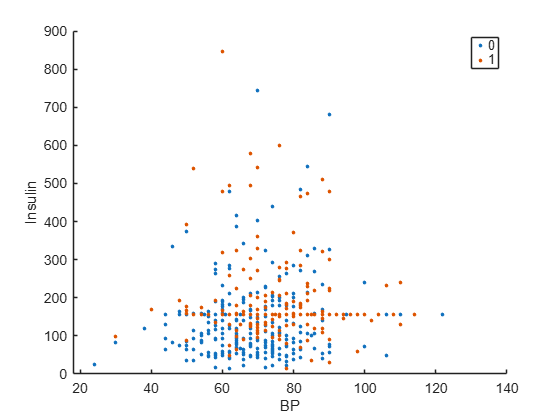

gscatter(Processed_Data.Diastolic_BP,Processed_Data.Serum_Insulin,Processed_Data.Class)
xlabel("BP")
ylabel('Insulin')

Inputs(Glucose,BP,Insulin,BMI) vs Output(Class)

SummaryTable=grpstats(Processed_Data,"Class",["mean","median","std"],...
    "DataVars",["Glucose","Diastolic_BP","Serum_Insulin","BMI"])

SummaryTable = 2×14 table
         Class    GroupCount    mean_Glucose    median_Glucose    std_Glucose    mean_Diastolic_BP    median_Diastolic_BP    std_Diastolic_BP    mean_Serum_Insulin    median_Serum_Insulin    std_Serum_Insulin    mean_BMI    median_BMI    std_BMI
         _____    __________    ____________    ______________    ___________    _________________    ___________________    ________________    __________________    ____________________    _________________    ________    __________    _______

    <